%% Day 1 - Getting Started Exercises

% Exercise 1: Compute 15 percent of 240
15/100 * 240

ans = 36


% Exercise 2: Area of a circle with radius 5
r = 5;                    
area = pi * r^2           

area = 78.5398


% Exercise 3: Square root of 2, then square it back
s = sqrt(2);              
s^2                       

ans = 2.0000












%% Day 2 - Variables and Data Types Exercises

% Exercise 1: Create a number and some text
temp = 72.5;              
city = "Boston";          

% Exercise 2: Make a list of temperatures for 5 days
highs = [70 75 78 74 80]; 

% Exercise 3: Make a struct (like a mini-database)
car.make = "Toyota";      
car.year = 2020;          

% Exercise 4: Check what type each variable is
class(temp)               % Should say "double"

ans = 'double'

class(city)               % Should say "string"

ans = 'string'

class(highs)              % Should say "double"

ans = 'double'

class(car)                % Should say "struct"

ans = 'struct'


% See everything you've created
whos                      % Shows all variables with sizes and types

  Name                             Size             Bytes  Class     Attributes

  angle_of_launch                  1x1                  8  double              
  ans                              1x6                 12  char                
  area                             1x1                  8  double              
  car                              1x1                438  struct              
  city                             1x1                166  string              
  gravity                          1x1                  8  double              
  height                           1x100              800  double              
  highs                            1x5                 40  double              
  initial_horizontal_velocity      1x1                  8  double              
  initial_vertical_position        1x1                  8  double              
  initial_vertical_velocity        1x1                  8  double              
  maximum_height                   1x1 
















%% Day 3 - Operators and Basic Math Exercises

% Exercise 1: Play with a=27 and b=4
a = 27;
b = 4;

a / b                    

ans = 6.7500

a^2                      

ans = 729

mod(a, b)                

ans = 3


% Exercise 2: Element-wise operations on a vector
v = [2 4 6 8 10];        
v.^2                     

ans =      4    16    36    64   100


v / 2                    

ans =      1     2     3     4     5



% Exercise 3: Count adults in a group
ages = [16 17 18 15 19]; 
adult_check = ages >= 18 

adult_check = 1×5 logical array
   0   0   1   0   1


sum(adult_check)        

ans = 2


















%% Day 4 - Vectors, Indexing and Slicing Exercises

% Exercise 1: Build a vector from 5 to 50 in steps of 5
v = 5:5:50;              % Makes: [5, 10, 15, ..., 50]

v(1)                     % First element = 5

ans = 5

v(end)                   % Last element = 50

ans = 50

v(3:6)                   % Elements 3 through 6 = [15 20 25 30]

ans =     15    20    25    30



% Exercise 2: Filter prices above 15
prices = [12 19 7 23 15 30 8];
expensive = prices(prices > 15)  % Keeps only > 15: [19 23 30]

expensive =     19    23    30



% Exercise 3: Count how many prices are below 10
cheap_count = sum(prices < 10)   

cheap_count = 2


% Exercise 4: Price floor - set everything below 10 to 10
prices(prices < 10) = 10;
















%% Day 5 - Loops and Conditionals Exercises
% Making decisions and repeating code

% Exercise 1: Temperature description with if/elseif
temp = 75;

if temp < 32
    disp('freezing');
elseif temp < 50
    disp('cold');
elseif temp < 75
    disp('warm');
else
    disp('hot');
end

hot



% Try changing temp to different values to see different outputs!

% Exercise 2: Compute 6! (6 factorial) with a for loop
factorial_result = 1;    

for k = 1:6              
    factorial_result = factorial_result * k;
end

disp(factorial_result)

   720




% Exercise 3: Halve until below 1, count steps
number = 100;
steps = 0;

while number >= 1
    number = number / 2;
    steps = steps + 1;
end


% Exercise 4: Sum of even numbers 2+4+...+100 (vectorized)
even_sum = sum(2:2:100);  % One line does the whole thing!
fprintf('Sum of evens 2 to 100 = %d\n', even_sum);

Sum of evens 2 to 100 = 2550













%% Day 6 - Functions Exercises
% Creating reusable math tools

% Exercise 1: Area of circle as an anonymous function
area = @(r) pi * r.^2;   

% Test it!
area(3)                  

ans = 28.2743


% Exercise 2: Function g(x) = sin(x) + x^2
g = @(x) sin(x) + x.^2;

% Test it on 5 points from 0 to pi
x_points = linspace(0, pi, 5);
g(x_points)              

ans =          0    1.3240    3.4674    6.2588    9.8696



% Exercise 3: Local function for range (max - min)

range_fn = @(v) max(v) - min(v);

% Test it
test_data = [10 25 3 18 7];
fprintf('Range = %d\n', range_fn(test_data));

Range = 22





%% Day 7 - Math Examples Exercises
% Solving real math problems with MATLAB

% Exercise 1: Solve system of equations
% 3x + 2y = 12
% x - y = 1

A = [3 2; 1 -1];         % Coefficients of x and y
b = [12; 1];             % Right-hand side

solution = A \ b;        % MATLAB solves it!
x = solution(1);
y = solution(2);

fprintf('x = %.1f, y = %.1f\n', x, y);

x = 2.8, y = 1.8


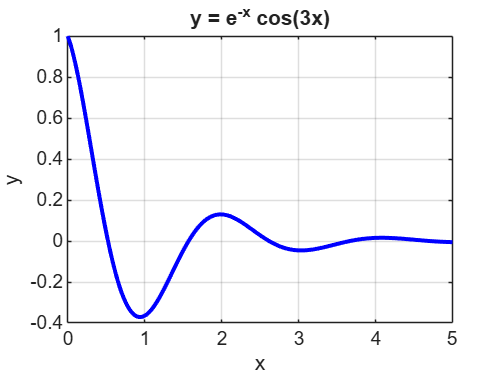


% Exercise 2: Plot y = e^(-x) * cos(3x)
x_plot = linspace(0, 5, 300);        % 300 points from 0 to 5
y_plot = exp(-x_plot) .* cos(3*x_plot);

figure(1);               % Creates a new figure window
plot(x_plot, y_plot, 'b-', 'LineWidth', 2);
grid on;                 % Adds grid lines
xlabel('x');
ylabel('y');
title('y = e^{-x} cos(3x)');


% Exercise 3: Area under y = x^2 from 0 to 3 using trapz
x_int = linspace(0, 3, 300);
y_int = x_int.^2;

area_approx = trapz(x_int, y_int);
fprintf('Area under x^2 from 0 to 3: %.4f\n', area_approx);

Area under x^2 from 0 to 3: 9.0001


fprintf('Exact answer is 9.0000\n');

Exact answer is 9.0000



% Exercise 4: Estimate slope of y = x^2 near x = 2
x_slope = linspace(1.5, 2.5, 200);
y_slope = x_slope.^2;

% diff() finds differences between consecutive points
slope_estimate = diff(y_slope) ./ diff(x_slope);

% Find the point closest to x=2
[~, closest_idx] = min(abs(x_slope(1:end-1) - 2));

fprintf('Estimated slope at x=2: %.4f\n', slope_estimate(closest_idx));

Estimated slope at x=2: 4.0000


fprintf('Exact slope is 4.0000\n');

Exact slope is 4.0000
